# Filter a Streaming Signal

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

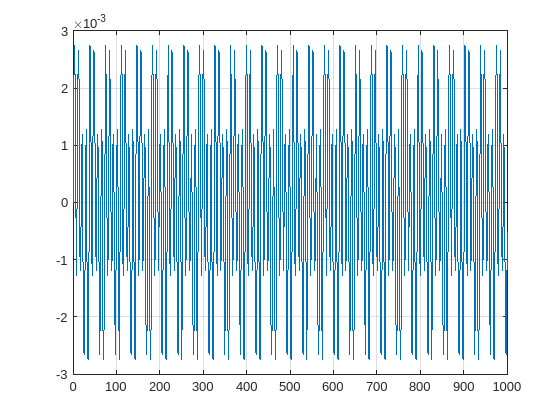

load ./data/monitoredfan.mat
src = dsp.SignalSource(monitoredfan,1000);
data = src();
plot(data)
grid on

bpFilt = designfilt("bandpassfir", ...
    "StopbandFrequency1",500,"PassbandFrequency1",570, ...
    "PassbandFrequency2",580,"StopbandFrequency2",600, ...
    "StopbandAttenuation1",60,"PassbandRipple",1, ...
    "StopbandAttenuation2",60,"SampleRate",fs);

## Task 1

If you've already designed your filter, or if you have a transfer function, you can filter a streaming signal using the coefficient vectors. You can get those coefficients from a digital filter with the `tf` method for the `designfilt` object.

`d` `=` `designfilt``(``...``)`

`[``b``,``a``]` `=` `tf``(``d``)`

[b,a] = tf(bpFilt)

b =     0.0002   -0.0002    0.0002   -0.0004   -0.0005    0.0001    0.0003   -0.0001   -0.0005    0.0000    0.0005    0.0000   -0.0006   -0.0001    0.0007    0.0002   -0.0008   -0.0004    0.0009    0.0006   -0.0010   -0.0008    0.0010    0.0011   -0.0010   -0.0014    0.0010    0.0017   -0.0009   -0.0021    0.0007    0.0024   -0.0004   -0.0028    0.0001    0.0031    0.0003   -0.0034   -0.0008    0.0036    0.0014   -0.0037   -0.0020    0.0038    0.0027   -0.0038   -0.0035    0.0036    0.0043   -0.0033


a = 1

## Task 2

Now you can make the FIR Filter using the System object:

`f` `=` `dsp.FIRFilter``(``b``)`

The first input to `dsp.FIRFilter` sets the numerator coefficients. If you were using an IIR filter, you'd set the `Denominator` as well by using two inputs.

fir = dsp.FIRFilter(b)

fir =   dsp.FIRFilter with properties:

            Structure: 'Direct form'
      NumeratorSource: 'Property'
            Numerator: [2.0561e-04 -2.3702e-04 1.7294e-04 -3.8656e-04 -5.0243e-04 6.6443e-05 3.4909e-04 -1.1901e-04 -4.6134e-04 4.1334e-05 5.3137e-04 1.5071e-05 -6.3947e-04 -1.1387e-04 7.4279e-04 2.3975e-04 -8.4402e-04 -4.0247e-04 … ] (1×238 double)
    InitialConditions: 0

  Show all properties


## Task 3

To use the filter, your filter object can be used as a function. For example, if your filter object was called `myfilt`, then you'd filter with:

`out` `=` `myfilt``(``in``)`

datafilt = fir(data)

datafilt = 1.0e-04 *

         0
    0.0035
    0.0016
    0.0021
   -0.0047
   -0.0180
   -0.0227
   -0.0127
   -0.0007
    0.0018


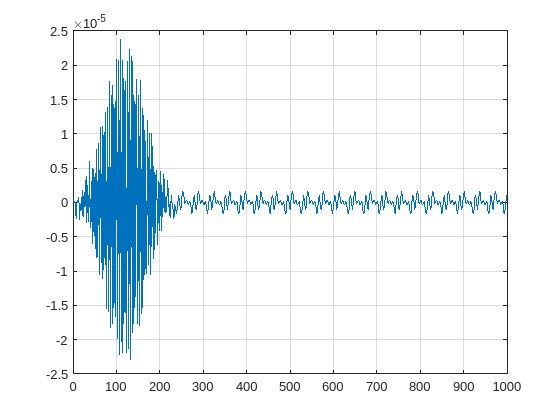

plot(datafilt)
grid on

## Task 4

You can see the filter transient at the beginning of the signal.

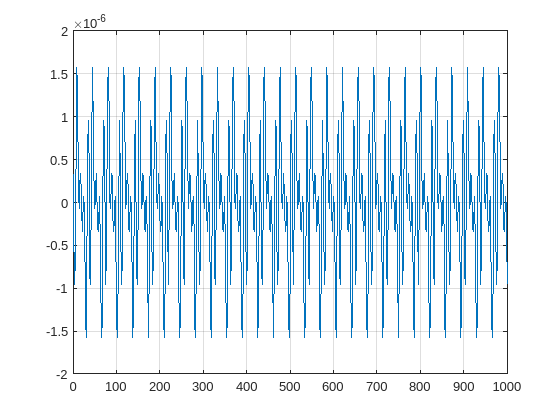

plot(fir(src()))
grid on